assert(endsWith(pwd, "\non-ferromagnetic metal plate with hole in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear

## Distributed Current Source

#### Coil

Coil.num = 1;
Coil.inner_radius = 3.75e-3; % (m)
Coil.outer_radius = 6.00e-3; % (m)
Coil.length       = 4.00e-3; % (m)

Coil.wire_diameter = 0.35e-3; % (m)
Coil.N_turns = 60;
Coil.conductivity = 6e7; % (S/m)
Coil.series_resistance = 0; % (Ohm)

Coil_pos = [-10e-3, 0, 4e-3]; % (m)
Coil = SetPositionRotation3D(Coil, Coil_pos, [1,0,0], deg2rad(0));
clear Coil_pos

#### Sensor

Sensor.num = 1;
Sensor.side_length = 1e-3;

Sensor_pos = [-10e-3, 0, 1.5e-3];
Sensor = SetPositionRotation3D(Sensor, Sensor_pos);
clear Sensor_pos

#### Model

vertex_file = 'square-l72_hole-d12_vertex.csv';
element_file = 'square-l72_hole-d12_element.csv';

h = 2e-3; % (m)
n_z = 1;
z = linspace(-h, 0, n_z+1);

Model = BuildModel3D('Extrude', vertex_file, element_file, 1e-3, z);

build model took 0.16 seconds


clear vertex_file element_file h n_z z

Model.conductivity = 7.407e5 * ones(1,Model.num_elems); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elems); % (1)
Model.relative_permeability = 1 * ones(1,Model.num_elems); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, Coil, Sensor);

build governing equation took 1.81 seconds


#### Solve in time domain

V_E = 1 ; % (V)
pulse_width = 3e-3; % (s)
voltage = @(t) V_E * (t > pulse_width*0.001 & t <= pulse_width*1.001);
Coil.time_domain.excitation = {"Voltage" voltage};
Coil.time_domain.time_span = [0, 6e-3]; % (s)
clear V_E pulse_width voltage

% I_E = 1; % (A)
% f = 2000; % (Hz)
% omega = 2*pi*f;
% Coil.time_domain.excitation = {"dCurrent_dt" @(t) I_E * omega * cos(omega*t)};
% Coil.time_domain.time_span = [0, 5e-4]; % (s)
% clear I_E f omega 

[Model, Coil, Sensor] = SolveTimeDomain3D(GoverningEquation, Model, Coil, Sensor);

solve in time domain took 22.80 seconds


#### Plot world

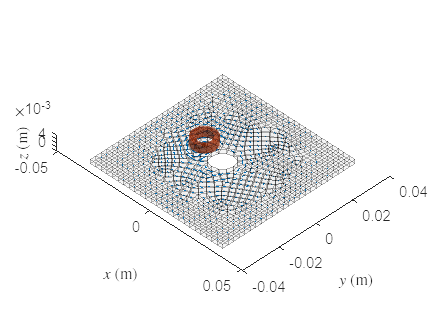

t = 0.4e-3; % (s)
[~,k] = min(abs(t - Model.time_domain.t));
J = Model.time_domain.J(:,:,k);
r = Model.elems_center;

figure
hold on
PlotWorld3D(Model, Coil, Sensor);
quiver3(r(1,:),r(2,:),r(3,:), J(1,:),J(2,:),J(3,:));


clear t k J r

#### Plot coil current

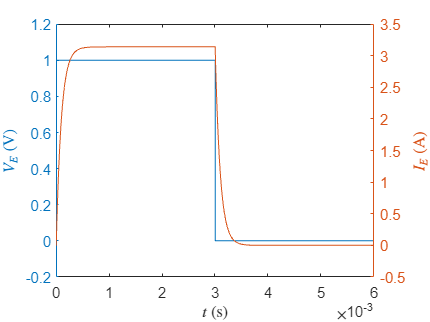

figure
yyaxis left
plot(Coil.time_domain.t, squeeze(Coil.time_domain.V(1,1,:)))
ylabel('$V_E$ (V)', 'Interpreter','latex')
yyaxis right
plot(Coil.time_domain.t, squeeze(Coil.time_domain.I(1,1,:)));
ylabel('$I_E$ (A)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')

## Compare with FEA

#### Read data

if strcmpi(Coil.time_domain.excitation{1,1}, 'dCurrent_dt')

data = readmatrix('FEA_data\current_excitation.txt', 'CommentStyle','%');
FEA.t = unique(data(:,2));
FEA.B_x = reshape(data(:,3), length(FEA.t), []);
FEA.B_y = reshape(data(:,4), length(FEA.t), []);
FEA.B_z = reshape(data(:,5), length(FEA.t), []);
FEA.B_E_x = FEA.B_x(:,2);
FEA.B_C_x = FEA.B_x(:,1) - FEA.B_E_x;
FEA.B_E_y = FEA.B_y(:,2);
FEA.B_C_y = FEA.B_y(:,1) - FEA.B_E_y;
FEA.B_E_z = FEA.B_z(:,2);
FEA.B_C_z = FEA.B_z(:,1) - FEA.B_E_z;

end

if strcmpi(Coil.time_domain.excitation{1,1}, 'voltage')

data = readmatrix('FEA_data\voltage_excitation.txt', 'CommentStyle','%');
FEA.t   = data(:,1);
FEA.B_x = data(:,2);
FEA.B_y = data(:,3);
FEA.B_z = data(:,4);
FEA.I   = data(:,5);
FEA.B_E_x = FEA.I * GoverningEquation.Beta_E_sensor(1);
FEA.B_C_x = FEA.B_x - FEA.B_E_x;
FEA.B_E_y = FEA.I / max(FEA.I) * max(FEA.B_y);
FEA.B_C_y = FEA.B_y - FEA.B_E_y;
FEA.B_E_z = FEA.I / max(FEA.I) * max(FEA.B_z);
FEA.B_C_z = FEA.B_z - FEA.B_E_z;

end

clear data

#### Magnetic flux density

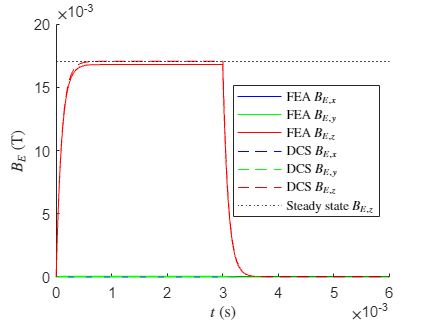

figure
hold on
plot(FEA.t, FEA.B_E_x, 'b-', 'DisplayName','FEA $B_{E,x}$')
plot(FEA.t, FEA.B_E_y, 'g-', 'DisplayName','FEA $B_{E,y}$')
plot(FEA.t, FEA.B_E_z, 'r-', 'DisplayName','FEA $B_{E,z}$')
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_E(1,1,:)), 'b--', 'DisplayName','DCS $B_{E,x}$')
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_E(2,1,:)), 'g--', 'DisplayName','DCS $B_{E,y}$')
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_E(3,1,:)), 'r--', 'DisplayName','DCS $B_{E,z}$')
yline(0.005420569132753 / GoverningEquation.R_coil, 'k:', 'DisplayName', 'Steady state $B_{E,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')

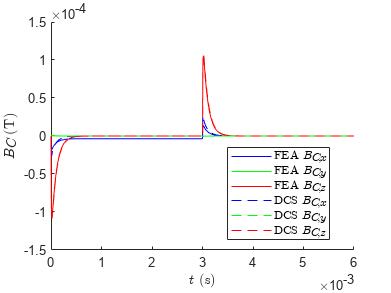


figure
hold on
plot(FEA.t, FEA.B_C_x, 'b-', 'DisplayName','FEA $B_{C,x}$')
plot(FEA.t, FEA.B_C_y, 'g-', 'DisplayName','FEA $B_{C,y}$')
plot(FEA.t, FEA.B_C_z, 'r-', 'DisplayName','FEA $B_{C,z}$')
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(1,1,:)), 'b--', 'DisplayName','DCS $B_{C,x}$')
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(2,1,:)), 'g--', 'DisplayName','DCS $B_{C,y}$')
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(3,1,:)), 'r--', 'DisplayName','DCS $B_{C,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')